cwd = pwd

cwd = '/Users/santosh/OneDrive - University College London/dev/amma/matlab'

tb99_file = fullfile(pwd, '..', 'datasets', 'tallest_99_buildings_aug2018.csv')
%[tall_rank, status, name, city, country, height_m, height_ft, no_floors, yr_completed, material, use] = ...

tb99_file = '/Users/santosh/OneDrive - University College London/dev/amma/matlab/../datasets/tallest_99_buildings_aug2018.csv'

%   textscan("../datasets/tallest_99_buildings_aug2018")
f = fopen(tb99_file)
% [tall_rank, status, name, city, country, height_m, height_ft, no_floors, yr_completed, material, use] = ...
%     textscan(f, '%u %s %s %s %s %f %f %u %u %s %s', 'Delimiter',',', 'HeaderLines',24)
C = textscan(f, '%u %s %s %s %s %f %f %u %u %s %s', 'Delimiter',',', 'HeaderLines',24)

f = 51

% T = readtable(tb99_file, 'Delimiter',',', 'HeaderLines',24)
% Table Summary
% summary(T)

T = 99×11 table
    Var1    Var2                   Var3                        Var4               Var5         Var6     Var7    Var8    Var9         Var10                        Var11              
    ____    _____    _________________________________    _______________    ______________    _____    ____    ____    ____    ________________    _________________________________

      1     'COM'    'Burj Khalifa'                       'Dubai'            'UAE'               828    2717    163     2010    'steel/concrete'    'office/residential/hotel'       
      2     'COM'    'Shanghai Tower'                     'Shan

tall_rank = C{1};
status = C{2};
name = C{3};


Variables:

    Var1: 99×1 double

        Values:

            Min          1  
            Median      50  
            Max         99  

    Var2: 99×1 cell array of character vectors

    Var3: 99×1 cell array of character vectors

    Var4: 99×1 cell array of character vectors

    Var5: 99×1 cell array of character vectors

    Var6: 99×1 double

        Values:

            Min       310.3 
            Median    343.7 
            Max         828 

    Var7: 99×1 double

        Values:

            Min        1018 
            Median     1128 
            Max        2717 

    Var8: 99×1 double

        Values:

            Min         52  
            Median      74  
            Max        163  

    Var9: 99×1 double

        Values:

            Min        1930 
            Median     2012 
            Max        2018 

  

city = C{5};
country = C{6};
height_m = C{7};
no_floors = C{8};
yr_completed = C{9};

ans = 2×11 table
    Var1    Var2                Var3                  Var4            Var5         Var6    Var7    Var8    Var9         Var10              Var11     
    ____    _____    __________________________    __________    ______________    ____    ____    ____    ____    ________________    ______________

     2      'COM'    'Shanghai Tower'              'Shanghai'    'China'           632     2073    128     2015    'composite'         'hotel/office'
     3      'COM'    'Makkah Royal Clock Tower'    'Mecca'       'Saudi Arabia'    601     1972    120     2012    'steel/concrete'    'other/hotel' 


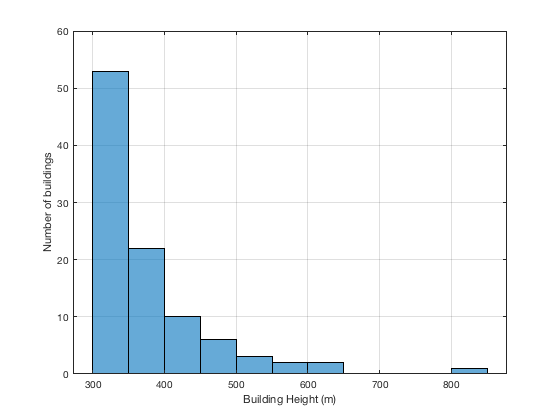

material = C{10};
use = C{11};
% T = csvread(tb99_file,25,1);

% opts = detectImportOptions(tb99_file)
% format_spec = '%u %s %s %s %s %f %f %u %u %s %s';
% T(2:3,:)

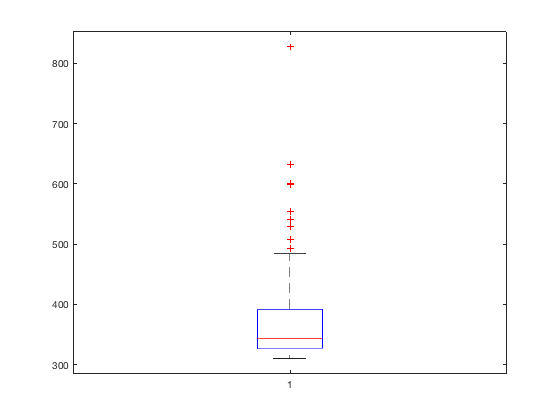

% element = T(2,'Var6');

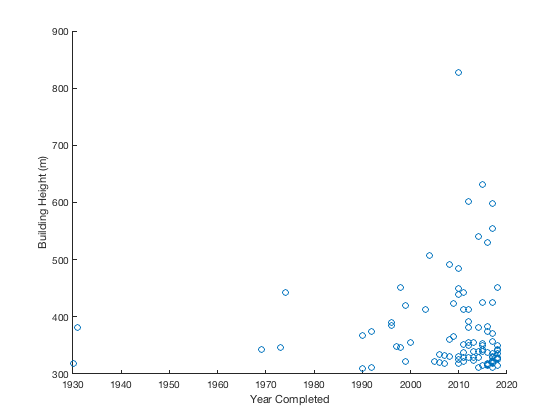

% ht_m = table2array(T(:,'Var6'));
% histogram(ht_m)
% 
% grid on

% xlabel('Building Height (m)')
% ylabel('Number of buildings')
% boxplot(ht_m)
% yr = table2array(T(:,'Var9'));
% scatter(yr,ht_m)
% xlabel('Year Completed')
% ylabel('Building Height (m)')